# Курс "Дискретные преобразования сигналов"

# Романюк Ю.А., Леус А.В., Тормагов Т.А.

# Лекция 1.

#### Классификация сигналов.

#### Аналоговые дискретные и цифровые сигналы.

#### Понятия дискретизации и квантования.

#### АЦП и шум квантования.

## 1.1. Классификация сигналов

**Сигнал** - физический процесс, несущий в себе информацию.

Под **сигналом** обычно понимают величину, отражающую состояние физической системы. Поэтому естественно рассматривать сигналы как функции, заданные в физических координатах. Примером могут служить одномерные сигналы, заданные как функции времени,  двумерные сигналы  заданные на плоскости,  и т. д.

В дальнейшем мы будем рассматривать в основном сигналы как действительные функции времени.

В качестве сигналов могут выступать различные величины:

- зависимость напряжения в сети от времени;


$$U=A\cdot \cos \left(2\pi \textrm{ft}\right)$$


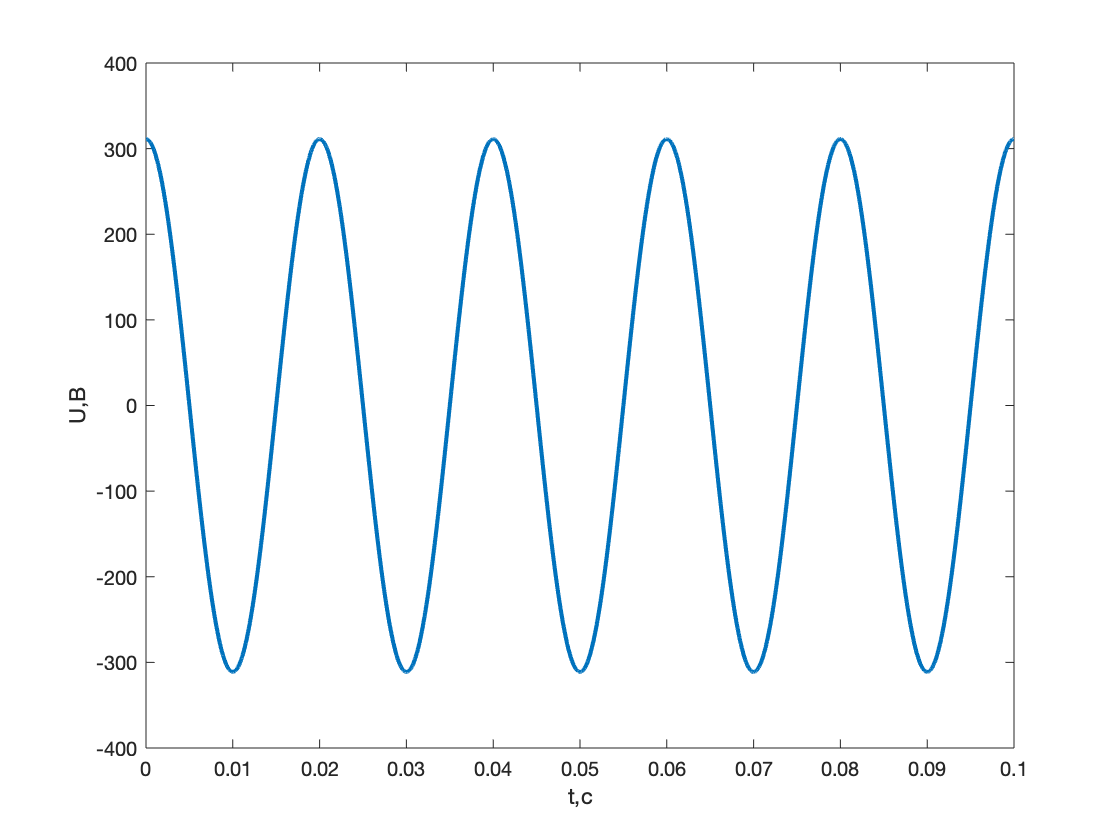

A = 220*sqrt(2);            % амплитуда
f=50;                       % частота
t=0:0.00001:0.09999;        % отображаемый временной интервал
U = A*cos(2*pi*f*t);        % зависимость напряжения от времени
% U = A*5*t;                  % линейный сигнал
plot(t,U,'LineWidth', 2); xlabel('t,c'); ylabel('U,В');

- зависимость температуры от времени;

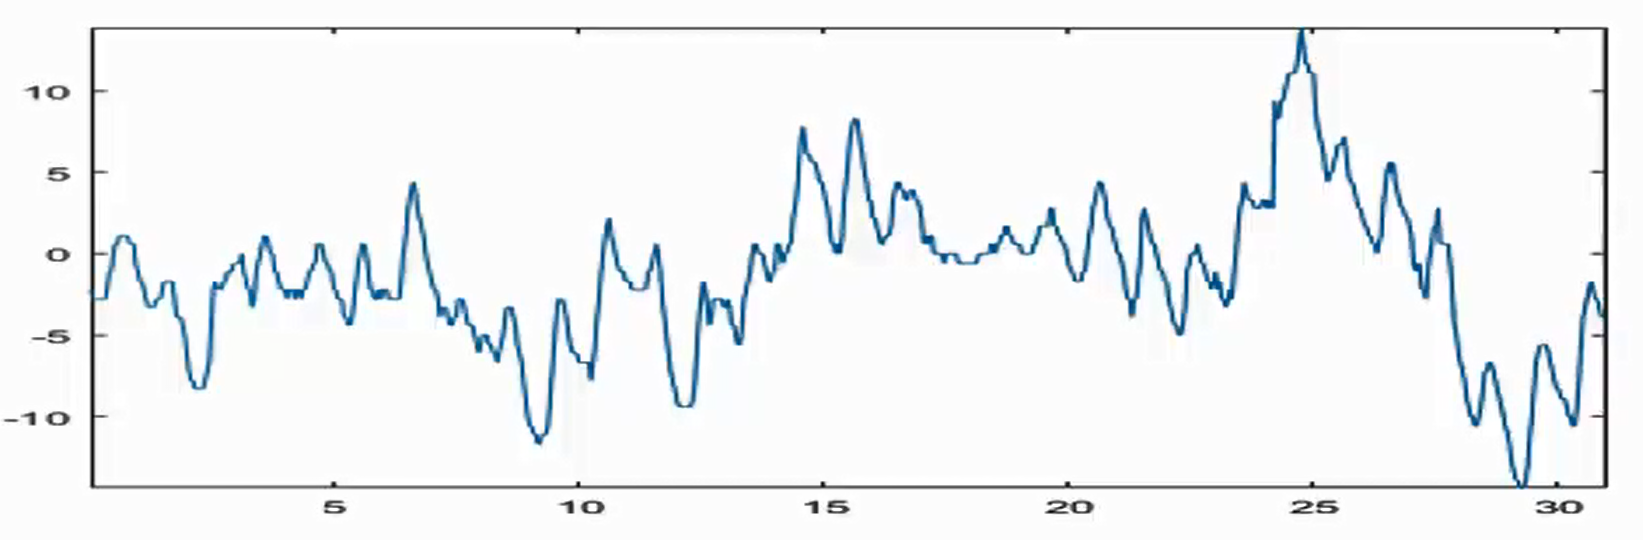

- электрокардиограмма;

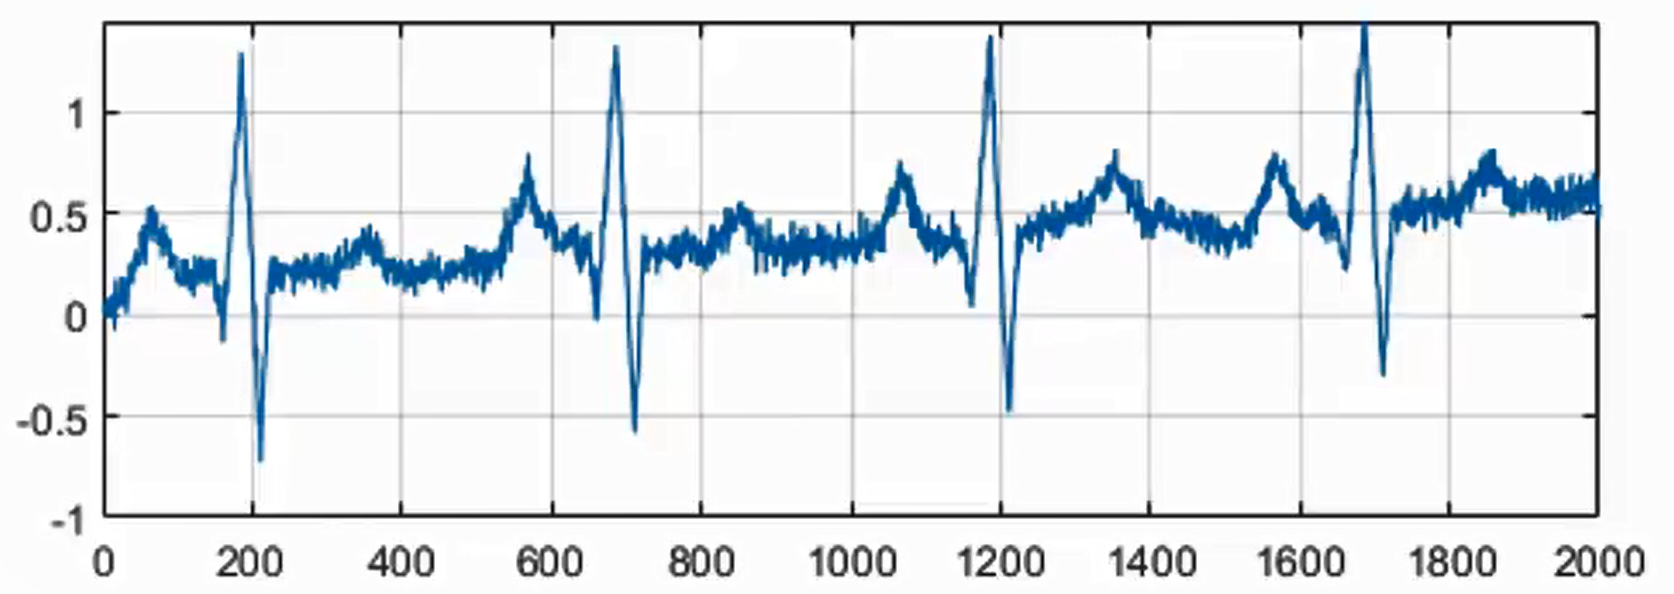

- речь человека;

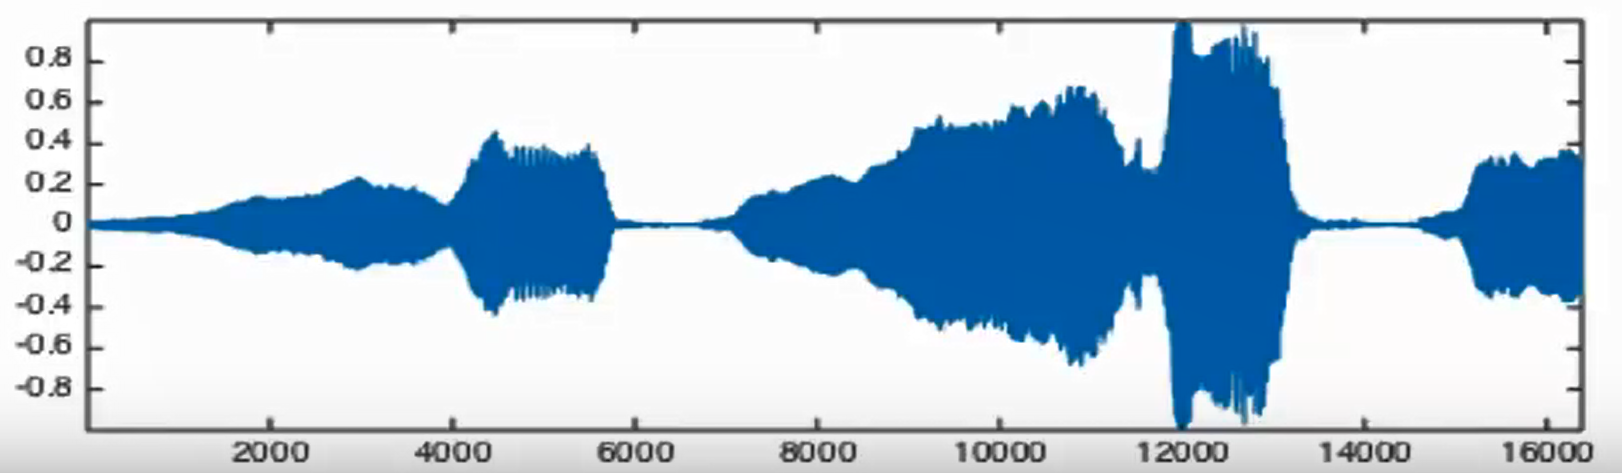

## Аналоговые дискретные и цифровые сигналы.

***Аналоговые*** или *континуальные *сигналы описываются непрерывными и кусочно-непрерывными функциями  причем как сама функция, так и ее аргумент могут принимать любые значения в пределах некоторого интервала.

***Дискретные*** сигналы $x_Д \left(t\right)$ образуются путём умножения аналогового сигнала $x\left(t\right)$ на так называемую функцию дискретизации $y\left(t\right)$ представляющую собой периодическую последовательность коротких импульсов, следующих с шагом дискретизации  $\Delta t$. 

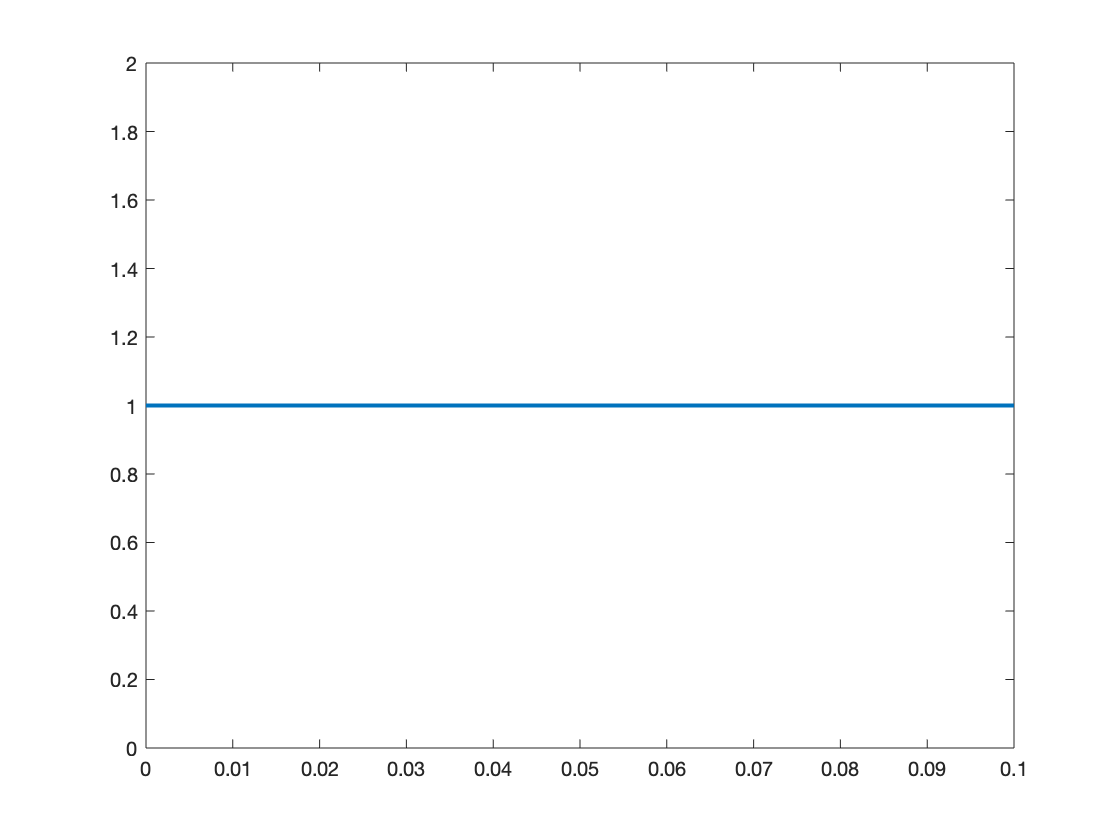

dT = 50; %*10 микросекунд
dt = 50;  %*10 микросекунд
y = [ones(1, dt) zeros(1, dT-dt)];
y = repmat(y,1,numel(t)/dT);
plot(t, y,'LineWidth', 2);

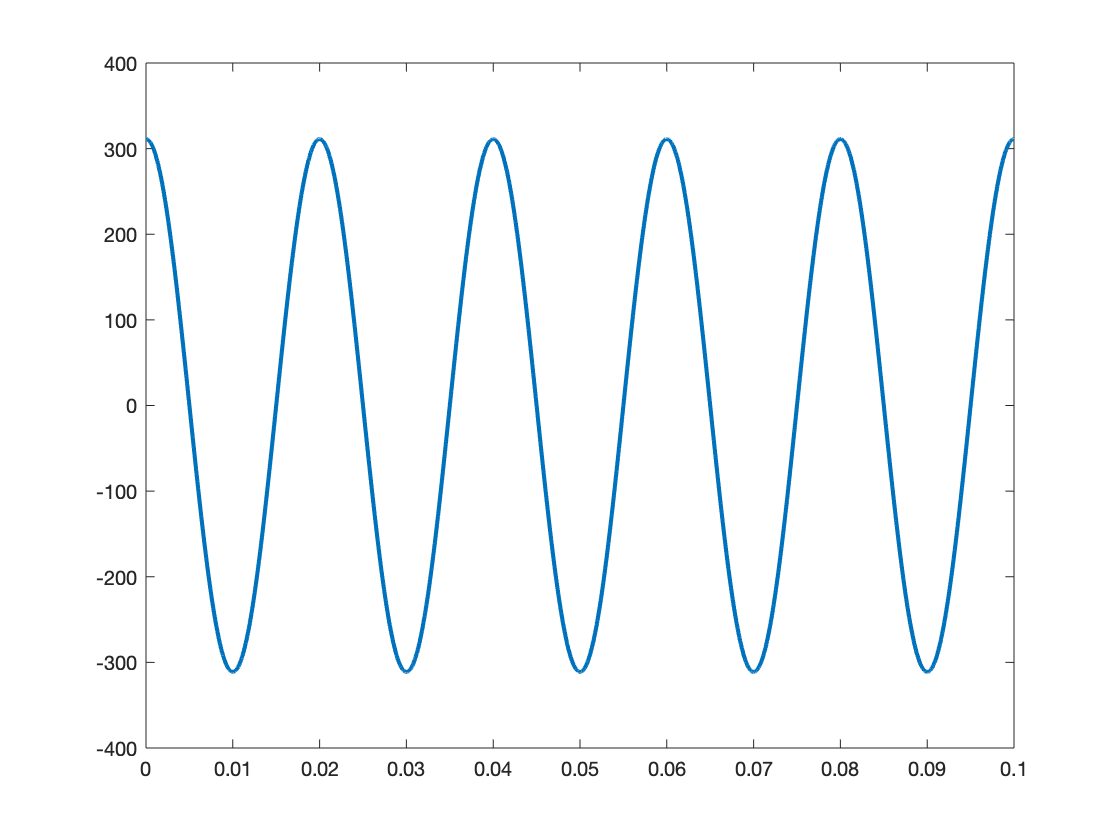

Ud = U.*y;
plot(t, Ud,'LineWidth', 2);

В идеальном случае в качестве функции дискретизации могут быть использована последовательность импульсов, продолжительность которых стремится к нулю.

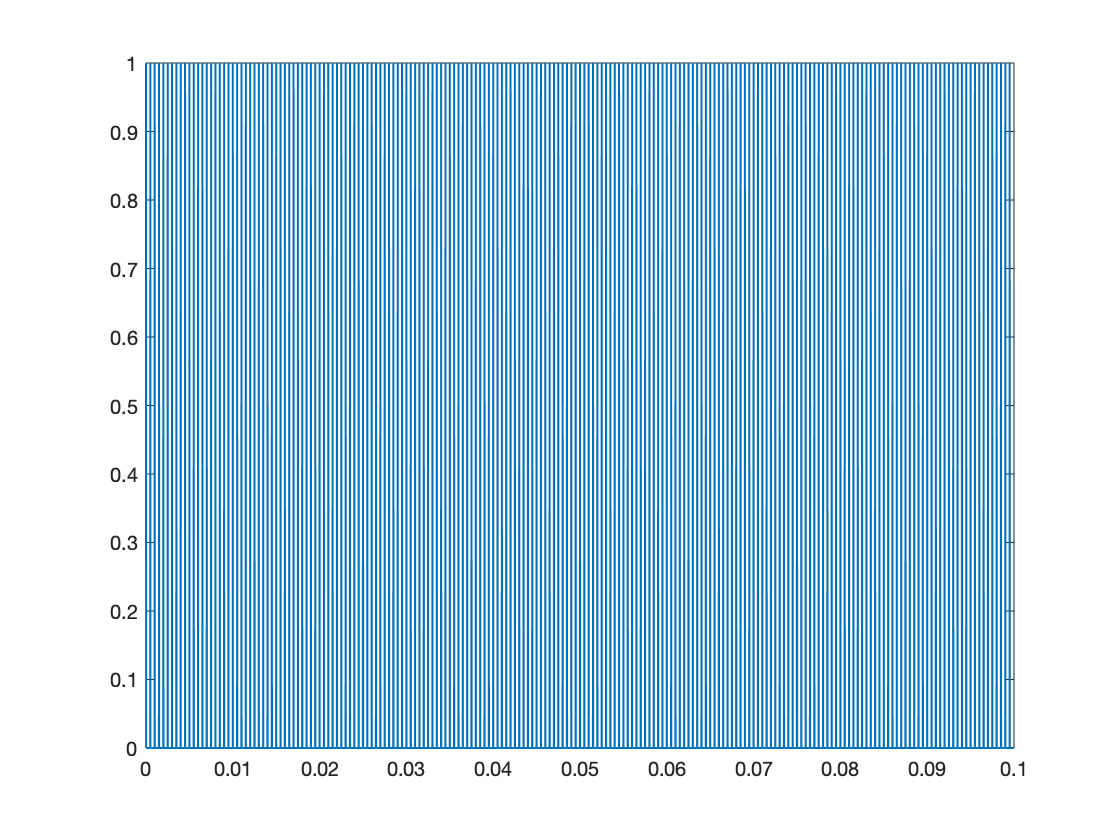

dt = 1;
y = [ones(1, dt) zeros(1, dT-dt)];
y = repmat(y,1,numel(t)/dT);
plot(t, y,'LineWidth', 1);

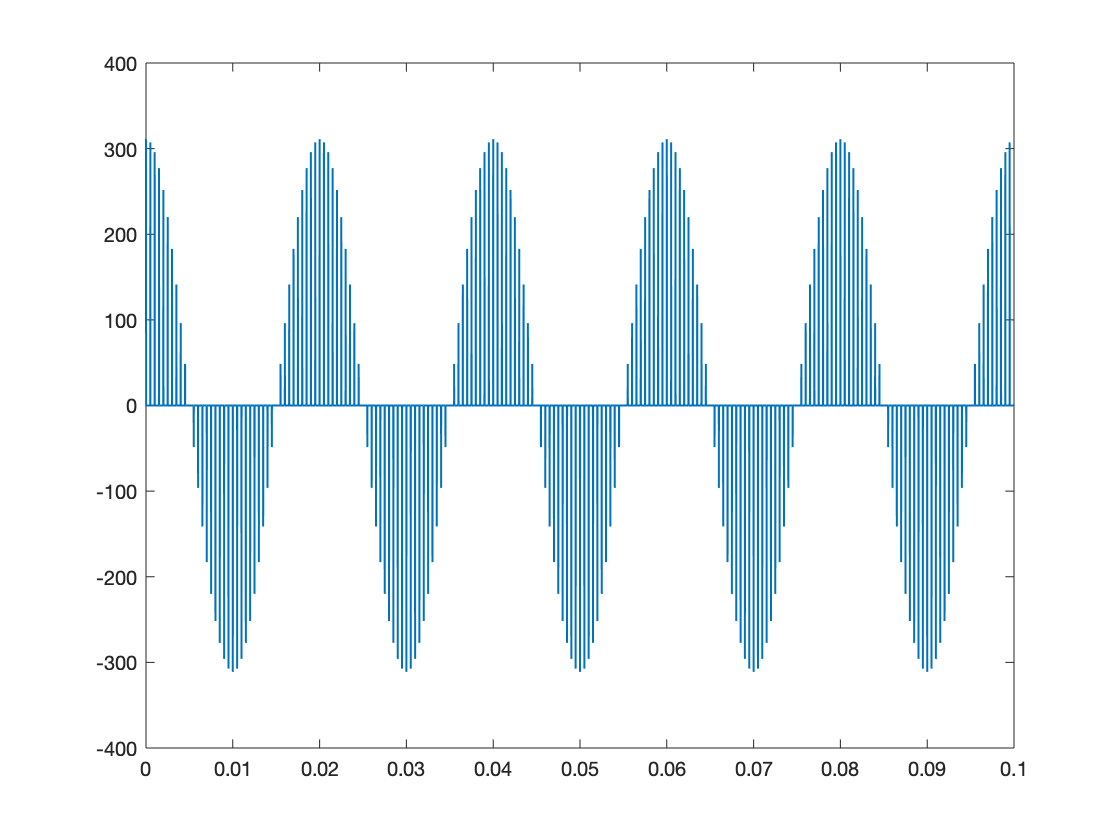

Ud = U.*y;
plot(t, Ud,'LineWidth', 1);

Для этого может быть использована периодическая последовательность дельта-функций.

**Дельта-функция** (функция Дирака) $\delta \left(x\right)$ имеет в значение 0 для всех *x* ≠ 0, и $\infty$ для x = 0

Для любой непрерывной непрерывной функции f и любого действительного числа a выполняется:


$$\int_{-\infty }^{\infty } \delta \left(x-a\right)f\left(x\right)\textrm{dx}=f\left(a\right)\ldotp$$


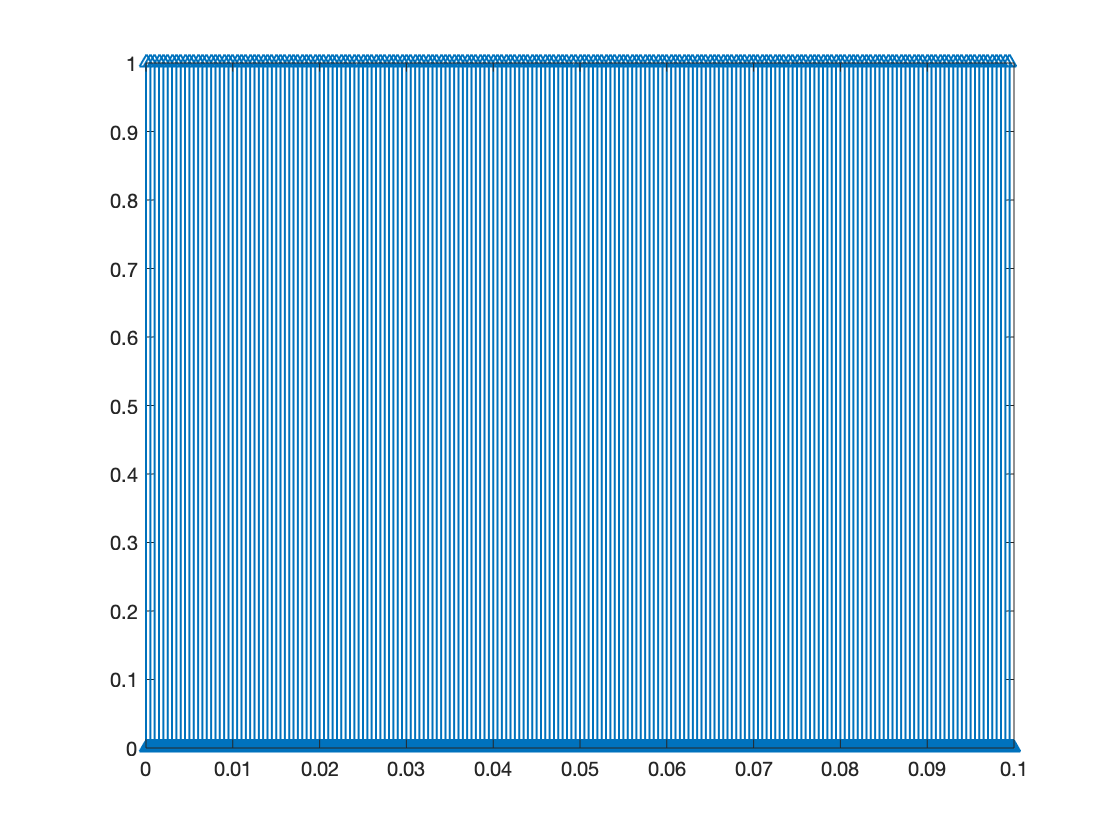

t1=0:dT-1;               % задаем временной интервал
delta = dirac(t1);                  % задаем дельта-функцию
delta = repmat(delta,1,numel(t)/dT);         % задаем последовательность дельта-функций
idx = delta == inf;                 % выделяем отсчеты, в которых дельта-функция ...
% равна бесконечности
delta(idx) = 1;                 % задаем значения в этих отсчетах равными 1
% (для визуализации)
stem(t,delta, 'LineWidth', 1, 'Marker', '^');        % строим график

Применение $\delta$-функции для дискретизации сигнала: вычисление свертки исходного сигнала и последовательности  $\delta$-функций:


$$\int_{-\infty }^{\infty } \sum_k \delta \left(t-t_k \right)f\left(x\right)\textrm{dx}=\sum_k \int_{-\infty }^{\infty } f\left(x\right)\delta \left(t-t_k \right)\textrm{dx}=\sum_k f\left(t_k \right)\ldotp$$


***Цифровой*** сигнал $x_ц \left(k\right)$ описывается квантованной решетчатой функцией, т. е. решетчатой функцией, принимающей лишь ряд дискретных уровней квантования $m\;q$  где  – $q$ шаг квантования по уровню, а  $m\;$– номер интервала квантования, $m=0,1,2,\ldotp \ldotp \ldotp ,M-1\ldotp$  Обычно $M=2^n ,\textrm{где}\;n$ –  целое положительное число.

M = 2^8;
m = 0:M-1;                          % номера квантования
A1 = A*1.01;                         % [-A1, A1] - диапазон, в котором идет квантование
Um =-A1+m*2*A1/M;                  % значения напряжений, соответствующие уровням
% квантования
Um1 = ones(numel(t),1) * Um;        % массив уровней квантования
plot(t,U, 'LineWidth', 2.5);        % исходный сигнал - зависимость напряжения от времени
xlabel('t,c'); ylabel('U,В');
hold on;
waitforbuttonpress;                 % ожидание нажатия кнопки
plot(t, Um1, t, y*A1, t, y*(-A1),... % график сетки
    'LineWidth', 0.5, 'Color', 'red');
waitforbuttonpress;
plot(t, Ud,'LineWidth', 1.5, 'Color', 'green');


На представленном графике видно, как оцифрованный сигнал зависит от периода функции дискретизации и уровней квантования.

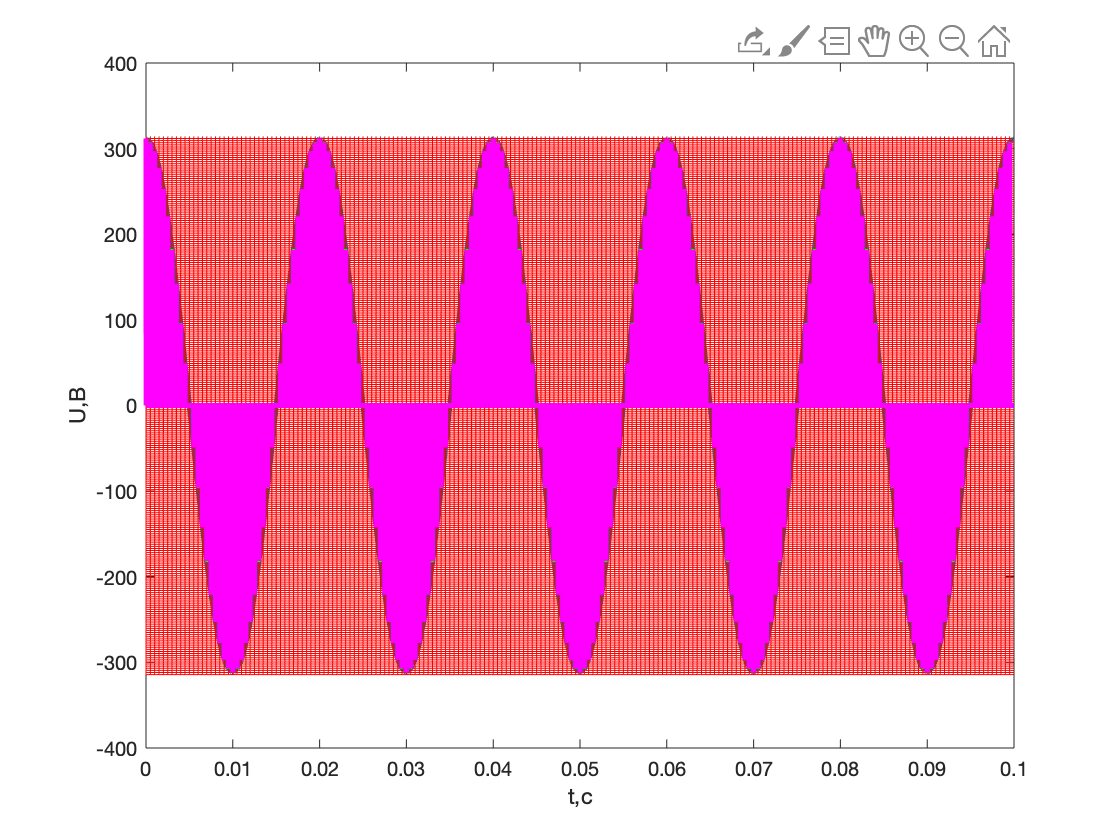

for k=1:numel(t)                    % находим ближайший уровень квантования
    [m, Nmin]=min(abs(Ud(k)-Um));
    Ud(k)=Um(Nmin);
end
waitforbuttonpress;
plot(t,Ud, 'LineWidth', 2.5, 'Color', 'm'); % график дискретизованного сигнала
waitforbuttonpress;
hold off;

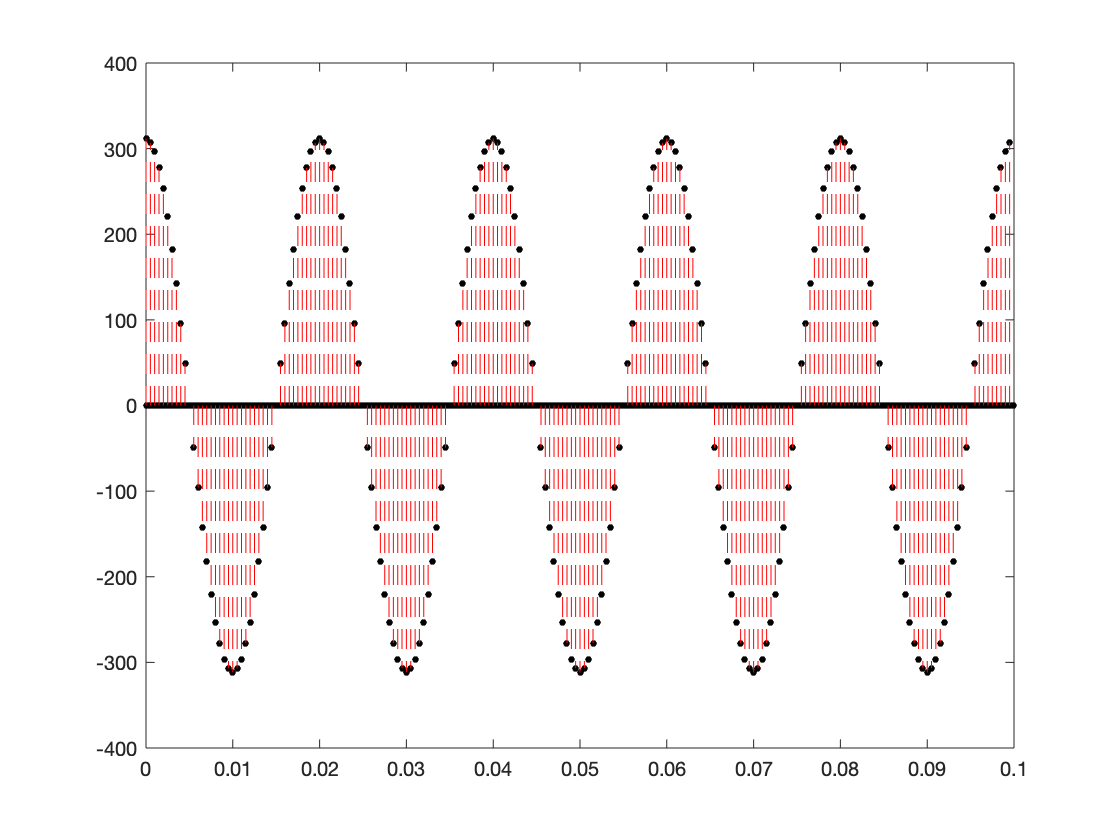

stem(t,Ud, 'LineWidth', 0.3, 'Color', 'r', 'LineStyle','--', ...
    'MarkerFaceColor','k', 'MarkerEdgeColor', 'k', 'MarkerSize', 3); % график оцифрованного сигнала

Проанализируем качество цифрового сигнала в зависимости от шага дискретизации dT = 100, 50, и числа уровней квантования: M = 2^2; 2^4; 2^8.

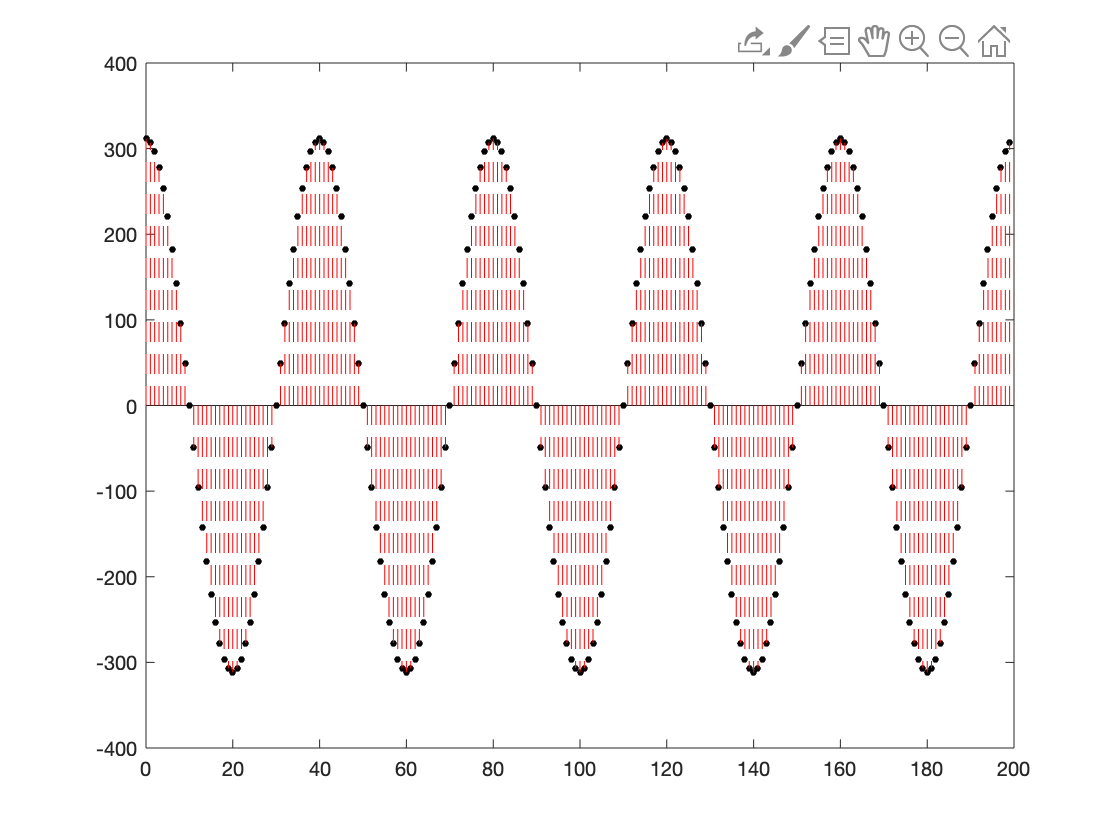

N = numel(t)/dT;
n = 0:(N-1);
Udn = Ud(1+n*dT);
stem(n, Udn, 'LineWidth', 0.3, 'Color', 'r', 'LineStyle','--', ...
    'MarkerFaceColor','k', 'MarkerEdgeColor', 'k', 'MarkerSize', 3); % график оцифрованного сигнала

Цифровой сигнал представляется последовательностями чисел, имеющих ограниченное количество разрядов. 

Большинство  информационных сигналов, получаемых от различных датчиков являются по своей форме *аналоговыми*, что означает непрерывное изменение во времени физических величин, например, напряжения, тока и т. д. В системах *цифровой обработки сигналов* (ЦОС), цифровые сигналы обычно получаются из аналоговых, дискретизованных через равные интервалы времени и преобразованных в цифровой вид. 

#### Основные преимущества ЦОС:

- *Гарантированная точность. *Точность определяется только числом задействованных битов в представлении сигналов и характеристик систем.

- *Совершенная воспроизводимость.*Цифровые записи можно копировать или воспроизводить многократно без ухудшения качества сигнала.

- *Большая гибкость.*Системы ЦОС можно запрограммировать и перепрограммировать на выполнение различных функций без изменения оборудования. Это важнейшая особенность ЦОС.

- *Превосходная производительность. *

- *Практически отсутствует зависимость характеристик от* *температуры и старения.*

## АЦП и шум квантования.

Для преобразования аналогового сигнала в цифровую форму в системах цифровой обработки сигналов используется аналого-цифровой  преобразователь (АЦП). АЦП формирует цифровые отсчёты сигналов, т.е. выполняет дискретизацию сигналов по времени и квантование отсчётов по уровню.

**Шум квантования ****n****-разрядного АЦП**

Передаточная функция идеального АЦП имеет вид:

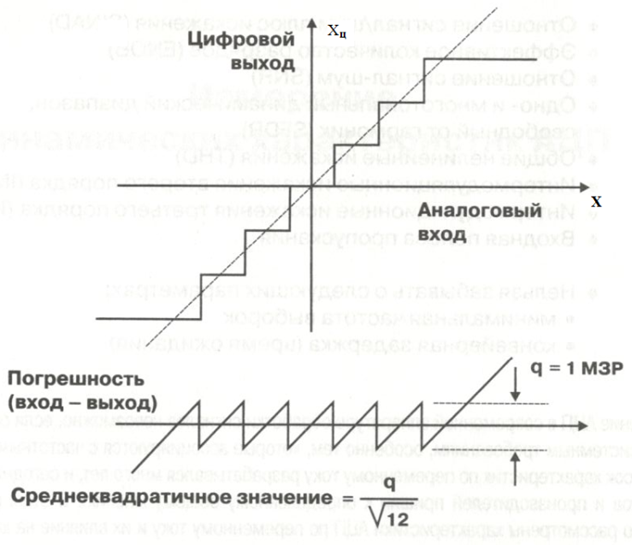

Погрешность квантования обозначим через $e=x-x_ц$. Как видно из графика передаточной функции максимальная погрешность при преобразовании сигнала равна $\pm \frac{1}{2}$ младшего значащего разряда (МЗР). Погрешность квантования сигнала с размахом, большим нескольких МЗР, можно аппроксимировать некоррелированной пилообразной ломанной с амплитудой от пика до пика, равной q - весу МЗР.

Пилообразная погрешность: 

$e\left(t\right)=s\cdot t,\textrm{где}\;-\frac{q}{2}<s\cdot t<\frac{q}{2}$.

q = 2*A1/M;             % Вес младшего значащего разряда
disp (q);

    2.4550



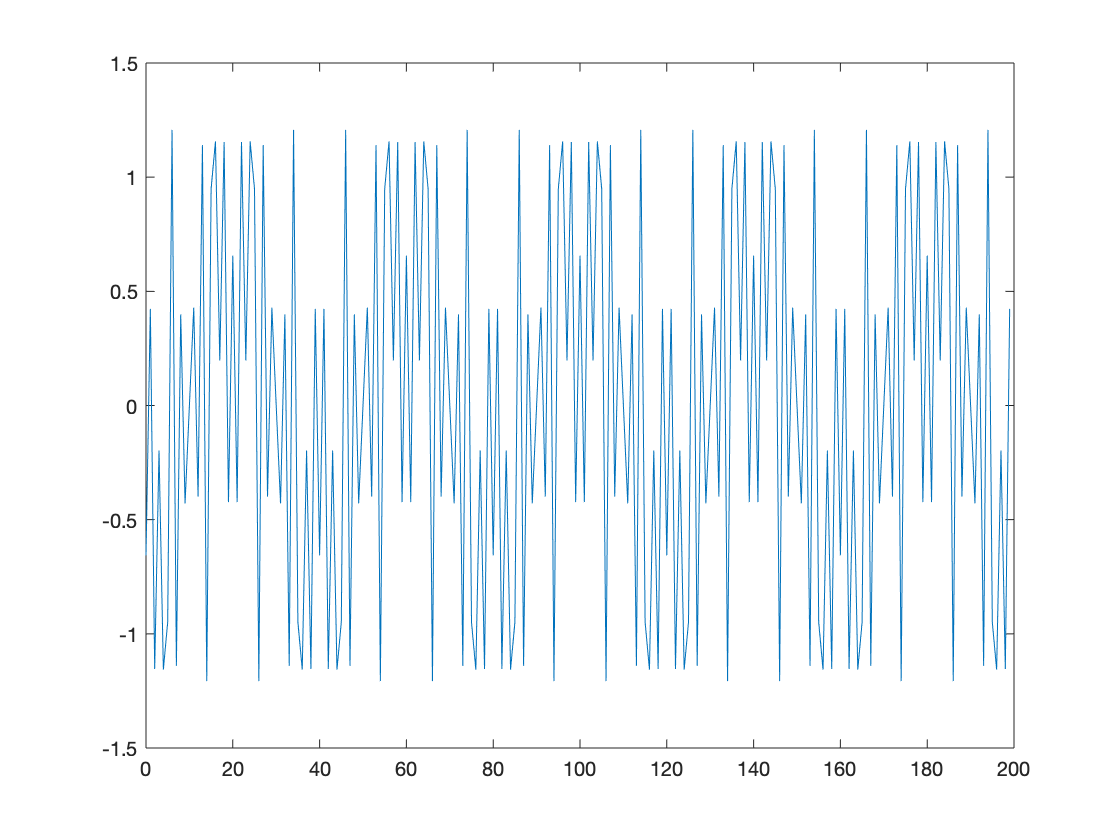

Un = U(1+n*dT);         % Отсчеты сигнала до квантования
e=Un-Udn;               % Погрешность квантования
plot (n, e);            % График погрешности квантования

max(e)-min(e)

ans = 2.4137

Подадим на вход линейный сигнал, чтобы получить пилообразную ломаную, описывающую шум квантования.

Шум квантования имеет равномерное распределение в пределах шага квантования:


$$p\left(e\right)=\frac{1}{q},\textrm{где}\;e\in \left\lbrack -\frac{q}{2};\frac{q}{2}\right\rbrack \ldotp$$


Ошибка квантования имеет среднее значение

$M\left\lbrack e\right\rbrack =\int_{-\frac{q}{2}}^{\frac{q}{2}} e\cdot p\left(e\right)\textrm{de}=0\ldotp$ и дисперсию

 
$$\sigma_e^2 ={M\left\lbrack e-M\left\lbrack e\right\rbrack \right\rbrack }^2 =M\left\lbrack e^2 \right\rbrack =\int_{-\frac{q}{2}}^{\frac{q}{2}} e^2 \cdot p\left(e\right)\textrm{de}=\frac{1}{q}\ldotp \int_{-\frac{q}{2}}^{\frac{q}{2}} e^2 \textrm{de}=\frac{q^2 }{12}\ldotp$$


Тогда среднеквадратичное значение шума квантования:


$$\sigma_e =\frac{q}{2\sqrt{3}}\ldotp$$


Me = mean(e)            % численный расчет мат.ожидания ошибки квантования

Me = -4.7784e-14

De = var(e)             % численный расчет дисперсии ошибки квантования

De = 0.7139

Sigma=q/(2*sqrt(3))     % теоретическое значение дисперсии для ошибки квантования

Sigma = 0.7087

Пусть на вход АЦП с диапазоном напряжения входного сигнала


$$V_{\textrm{in}} =\left\lbrack -\frac{q\cdot 2^n }{2},\frac{q\cdot 2^n }{2}\right\rbrack$$


подана синусоида $\;x\left(t\right)=\frac{q\cdot 2^n }{2}\sin \left(2\pi \textrm{ft}\right)\ldotp$

Среднеквадратичное значение входного сигнала $\sigma_x =\frac{q\cdot 2^n }{2\sqrt{2}}\ldotp$

Получаем отношение "сигнал / шум" (Signal to Noise Ration - SNR)


$$\textrm{SNR}=20\lg \left\lbrack \frac{\sigma_x }{\sigma_e }\right\rbrack =20\lg \left\lbrack \frac{q\cdot 2^n /2\sqrt{2}}{q/2\sqrt{3}}\right\rbrack =20\lg 2^n +20\lg \sqrt{\frac{3}{2}}=20n\cdot \textrm{lg2}+10\textrm{lg1},5=\left(6,02n+1,76\right)\textrm{дБ}\ldotp$$


Относительный уровень шума квантования


$$\gamma =20\lg \left\lbrack \frac{\sigma_e }{\sigma_x }\right\rbrack =-\left\lbrack 6,02n+1,76\right\rbrack \textrm{дБ}\ldotp$$


Для восьмиразрядного АЦП относительный уровнь шума квантования:


$$\gamma =-\left\lbrack 6,02\cdot 8+1,76\right\rbrack \approx -50\;\textrm{дБ}\ldotp$$


Me2 = (mean(U.*U))^0.5          % численный расчет среднеквадратичного значения входного сигнала

Me2 = 220.0000

SNR = 20*log10(Me2/De)          % численный расчет соотношения "сигнал/шум"

SNR = 49.7757

Sigmax=q*M/(2*sqrt(2))          % теоретическое значение среднеквадратичного входного сигнала

Sigmax = 222.2000

SNRT = 20*log10(Sigmax/Sigma)   % теоретический расчет соотношения "сигнал/шум"

SNRT = 49.9257

Рассмотрим процесс дискретизации и квантования на примере цифрового изображения:


f = imread('imgcar.jpeg');      % открываем изображение

Error using imread>get_full_filename (line 566)
File "imgcar" does not exist.

Error in imread (line 375)
    fullname = get_full_filename(filename);

imshow(f);                      % отображаем картинку
fr=f(:,:,1);                    % убираем цвет
imshow(fr);                     % отображаем картинку
plot(fr(1,:));                  % построение графика значения яркости 1й строки изображения
size = [300 400];
fr = imresize(fr, size);        % дискретизуем сигнал
imshow(fr);                     % отображаем дискретизованный сигнал
plot(fr(1,:));                  % построение графика значения яркости 1й строки изображения


Квантование сигнала

M=2^5;
m = 0:M-1;                              % номера квантования
A = round(255/M)                        %
fr=uint8(fix(double(fr)/A));
plot(fr(1,:));
fr=fr*A;                                % восстановаление изображения
imshow(fr);

Проверим качество изображения при его квантовании с M=2, 2^2, 2^4, 2^6, 2^8 (1-, 2-, 4-, 6-, 8-битное квантование)

## Ссылки:

[https://exponenta.ru/news/cifrovaya-obrabotka-signalov#17](https://exponenta.ru/news/cifrovaya-obrabotka-signalov#17)

[https://classroom.google.com/u/0/c/NDE5ODc1NTczMjJa](https://classroom.google.com/u/0/c/NDE5ODc1NTczMjJa)